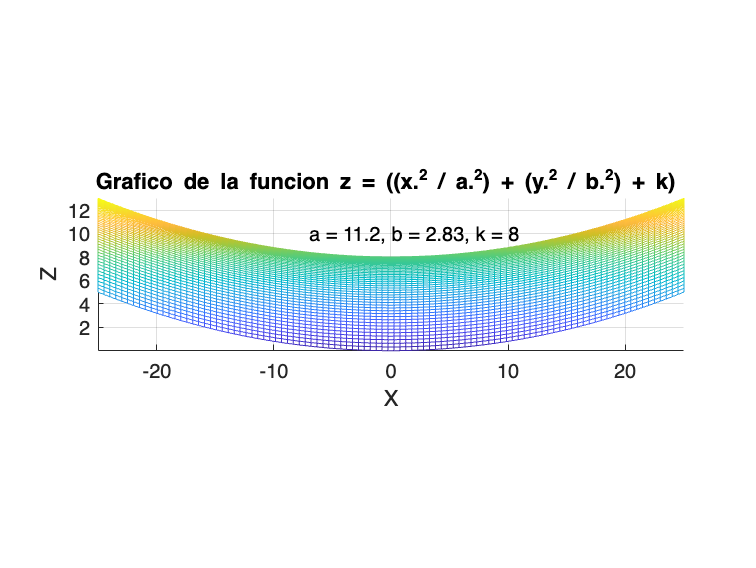

f = @(x, y, a, b, k) ((x.^2 / a.^2) - (y.^2 / b.^2) + k);

x = linspace(-25, 25, 100);
y = linspace(-8, 8, 100);

[X, Y] = meshgrid(x, y);

a = sqrt(125);
b = sqrt(8);
k = 8;

Z = f(X, Y, a, b, k);

figure;
mesh(X, Y, Z);
xlabel('X');
ylabel('Y');
zlabel('Z');
axis equal;
text(-7, 0, 10, sprintf('a = %.3g, b = %.3g, k = %d', a, b, k));
title('Grafico de la funcion z = ((x.^2 / a.^2) + (y.^2 / b.^2) + k) ');
view([0 0])

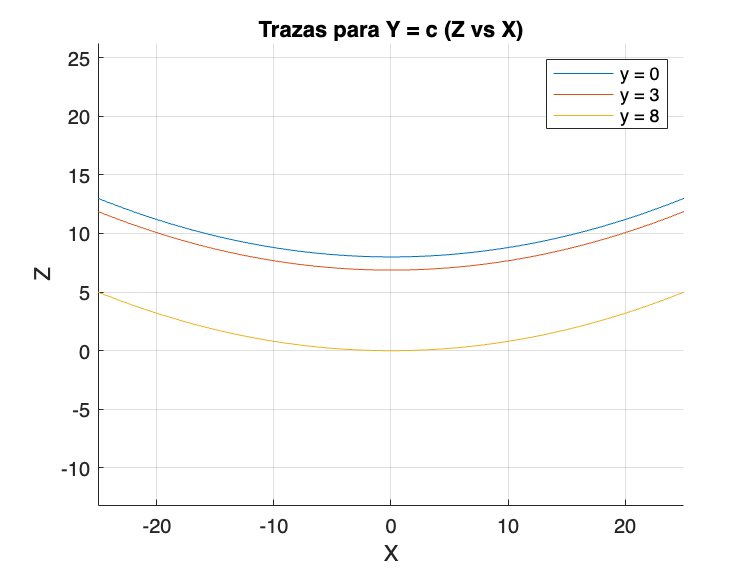

ycvalues = [0, 3, 8];
xcvalues = [0, 10, 25];
zcvalues = [8, 9.5 11, 12.5];

%% Traza Y = c (Z en función de X)
figure;
hold on;
for i = 1:length(ycvalues)
    z = f(x, ycvalues(i), a, b, k);
    plot(x, z, 'DisplayName', sprintf('y = %d', ycvalues(i)));
end
xlabel('X');
ylabel('Z');
title('Trazas para Y = c (Z vs X)');
legend;
grid on;
axis equal;
hold off;

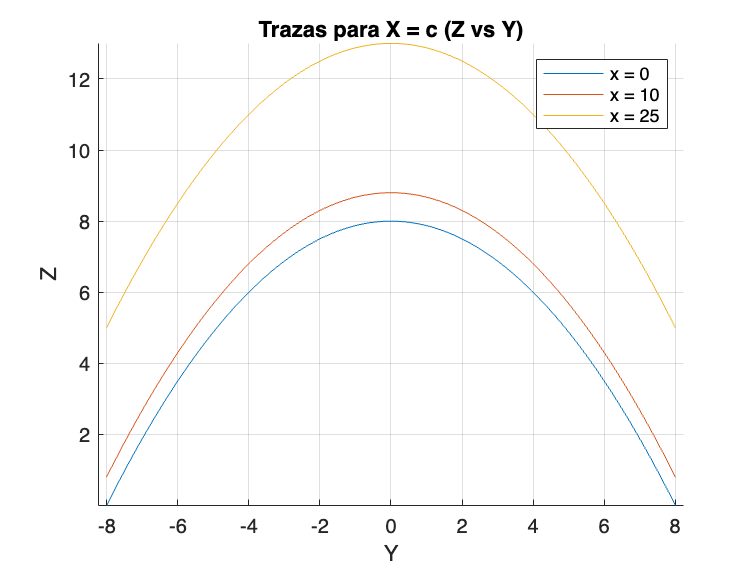


%% Traza X = c (Z en función de Y)
figure;
hold on;
for i = 1:length(xcvalues)
    z = f(xcvalues(i), y, a, b, k);
    plot(y, z, 'DisplayName', sprintf('x = %d', xcvalues(i)));
end
xlabel('Y');
ylabel('Z');
title('Trazas para X = c (Z vs Y)');
legend;
grid on;
axis equal;
hold off;

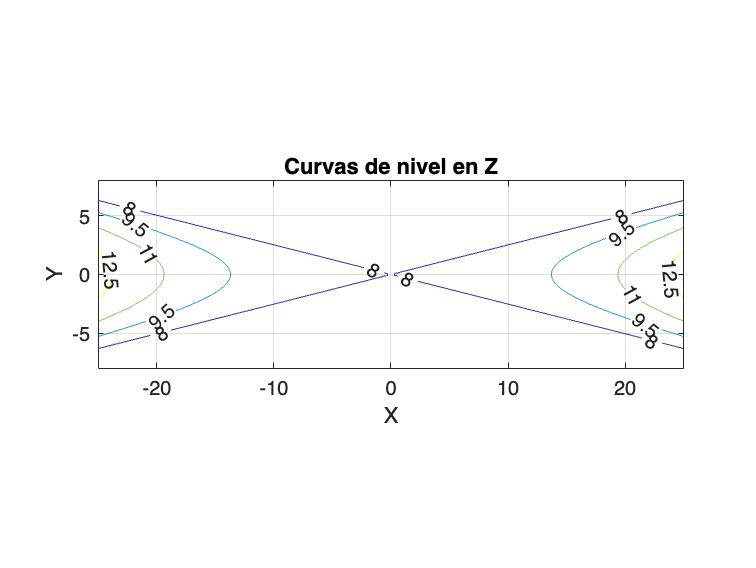


% Z = c
figure;
contour(X, Y, Z, zcvalues, 'ShowText','on');
xlabel('X');
ylabel('Y');
title('Curvas de nivel en Z');
grid on;
axis equal;